# Probability Distributions in MATLAB

## Creating Probability Distributions in MATLAB

`makedist`

`pd = ``makedist``(``distname``)`

`pd = ``makedist``(``distname,Name,Value``)`

`list = ``makedist`

- Creates a probability distribution object in MATLAB

- `distname` must be a name of a known distribution, see `doc ``makedist`

- `Name` and `Value` values depend upon the probability distribution you create

- `list = makedist `returns a list of possible distributions

meanhm = 5;
meanhf = 2;
stdhm = 0.3;
stdhf =0.5;
pdnm = makedist('Normal','mu',meanhm,'sigma',stdhm)

pdnm =   NormalDistribution

  Normal distribution
       mu =   5
    sigma = 0.3


pdnf = makedist('Normal','mu',meanhf,'sigma',stdhf)

pdnf =   NormalDistribution

  Normal distribution
       mu =   2
    sigma = 0.5


list=makedist

list = 27×1 cell array
    {'beta'                   }
    {'binomial'               }
    {'birnbaumsaunders'       }
    {'burr'                   }
    {'exponential'            }
    {'extremevalue'           }
    {'gamma'                  }
    {'generalizedextremevalue'}
    {'generalizedpareto'      }
    {'halfnormal'             }
    {'inversegaussian'        }
    {'logistic'               }
    {'loglogistic'            }
    {'lognormal'              }
    {'multinomial'            }
    {'nakagami'               }
    {'negativebinomial'       }
    {'normal'                 }
    {'piecewiselinear'        }
    {'poisson'                }
    {'rayleigh'               }
    {'rician'                 }
    {'stable'                 }
    {'tlocationscale'         }
    {'triangular'             }
    {'uniform'                }
    {'weibull'                }

## Evaluating a distribution

`pdf`**– ****ain’t**** just a file format**

- Takes a probability distribution and evaluates it at values of `x`

- `‘name’ `is the name of a specific distribution that is coded into MATLAB, with parameters `A`, `B`, …

- You may also can pass a probability distribution object (made from `makedist`) to 

y = pdf(pdnm,4.8:0.1:5.3)

y =    1.064826685074507   1.257944092309977   1.329807601338109   1.257944092309978   1.064826685074507   0.806569081730478


## Plotting a Distribution

- Use pdf to calculate the values for a certain range of x

- Could also use `probplot `to superimpose a probability distribution on a data set to measure how well the data conforms to the probability distribution.

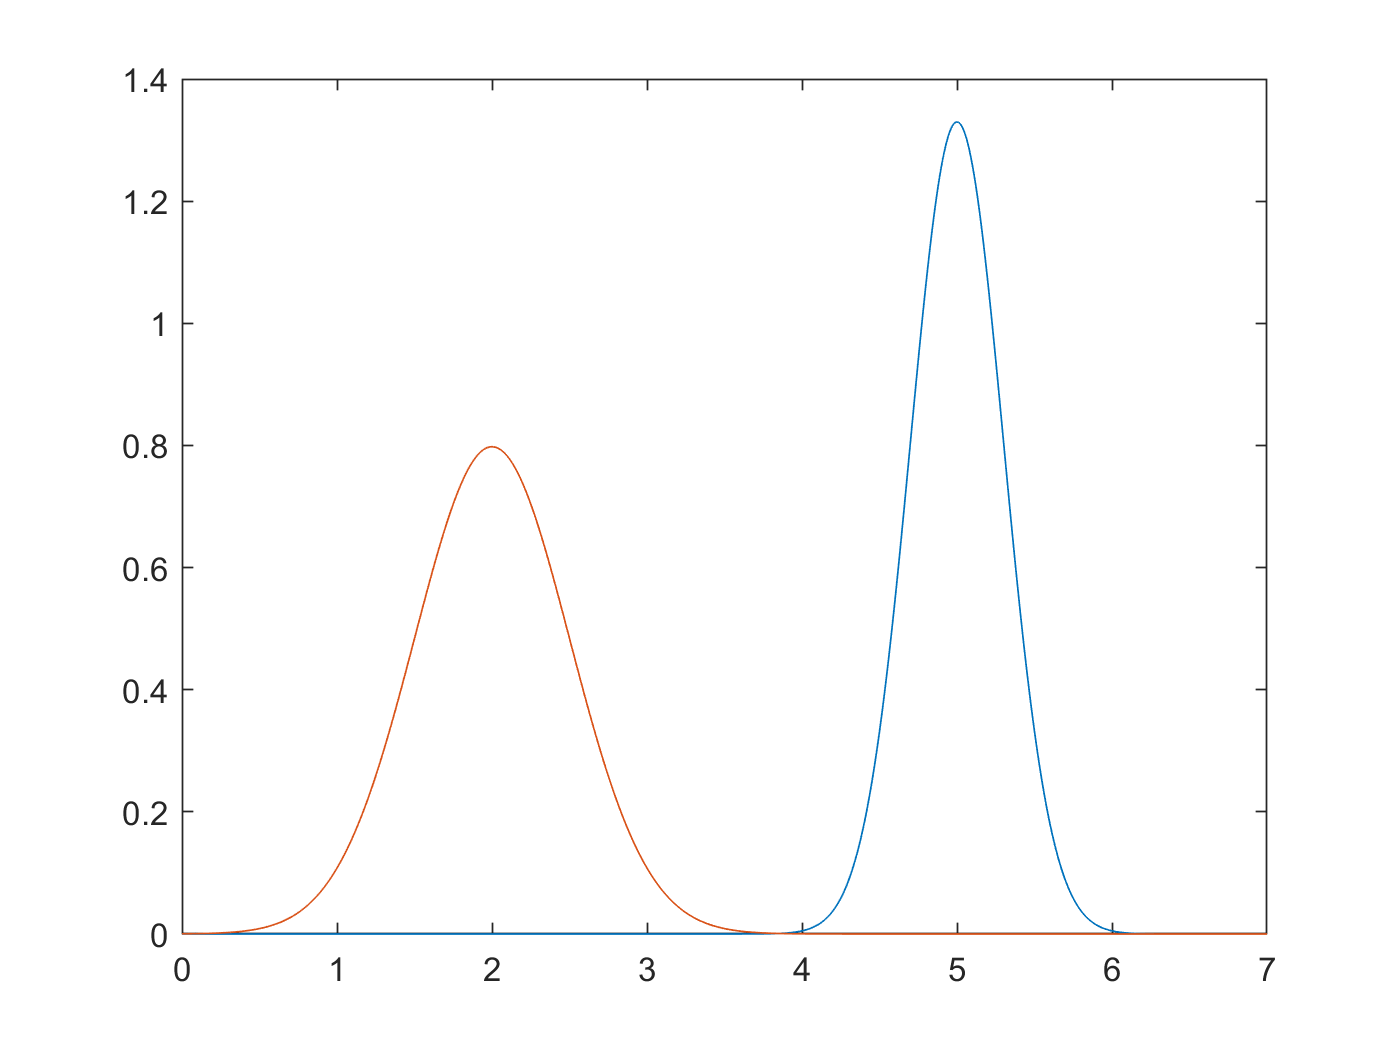

x = 0:0.01:7;
plot(x,pdf(pdnm,x),x,pdf(pdnf,x))

## Cumulative Probability Distributions

- Cumulative probability distributions give the  probability that a quantity will take a value less than or equal to *x*

- Use MATLAB function `cdf` to return, graph, and manipulate cumulative probability distributions

The 'binomial' distributions returns the number of 'heads' in a number of coin flips *N*, where heads shows up with a probability of *p. *It is only defined for integer inputs

pdb = makedist('Binomial','N',50,'p',0.50)

pdb =   BinomialDistribution

  Binomial distribution
    N =  50
    p = 0.5


pdf(pdb,20:30)'

ans =    0.041859149252552
   0.059798784646503
   0.078825670670390
   0.095961686033519
   0.107956896787709
   0.112275172659217
   0.107956896787709
   0.095961686033519
   0.078825670670390
   0.059798784646503


cdb = cdf('Binomial',25,50,0.5)

cdb =    0.556137586329609

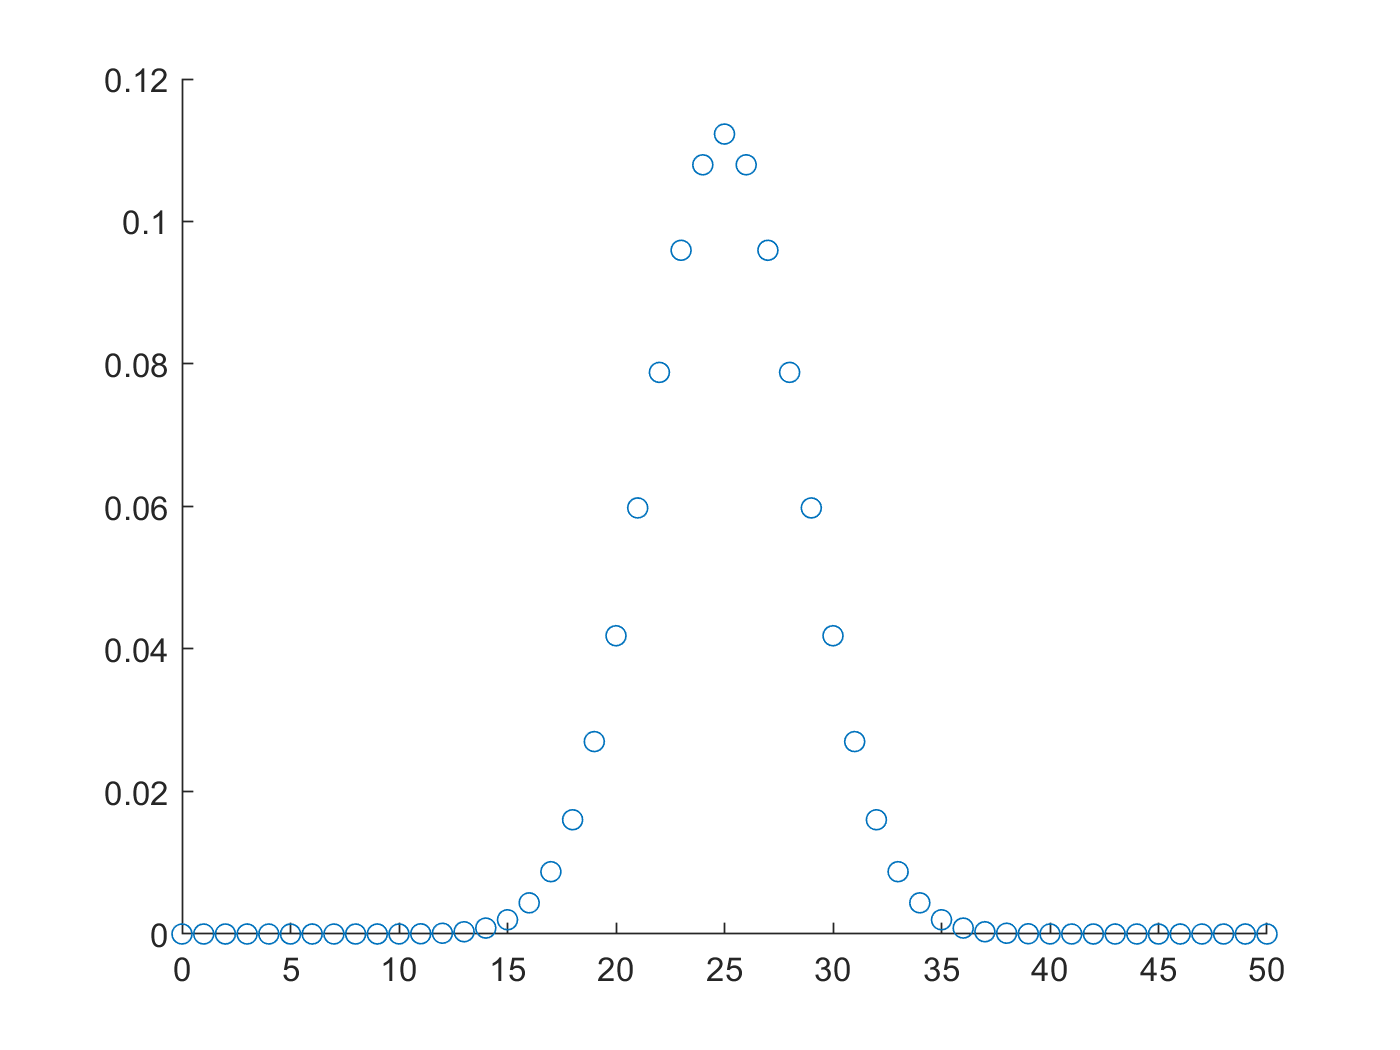

scatter(0:50,pdf(pdb,0:50))

fb = @(x) cdf('Binomial',x,50,0.5)

fb = function_handle with value:
    @(x)cdf('Binomial',x,50,0.5)

fb(22)

ans =    0.239943830849164

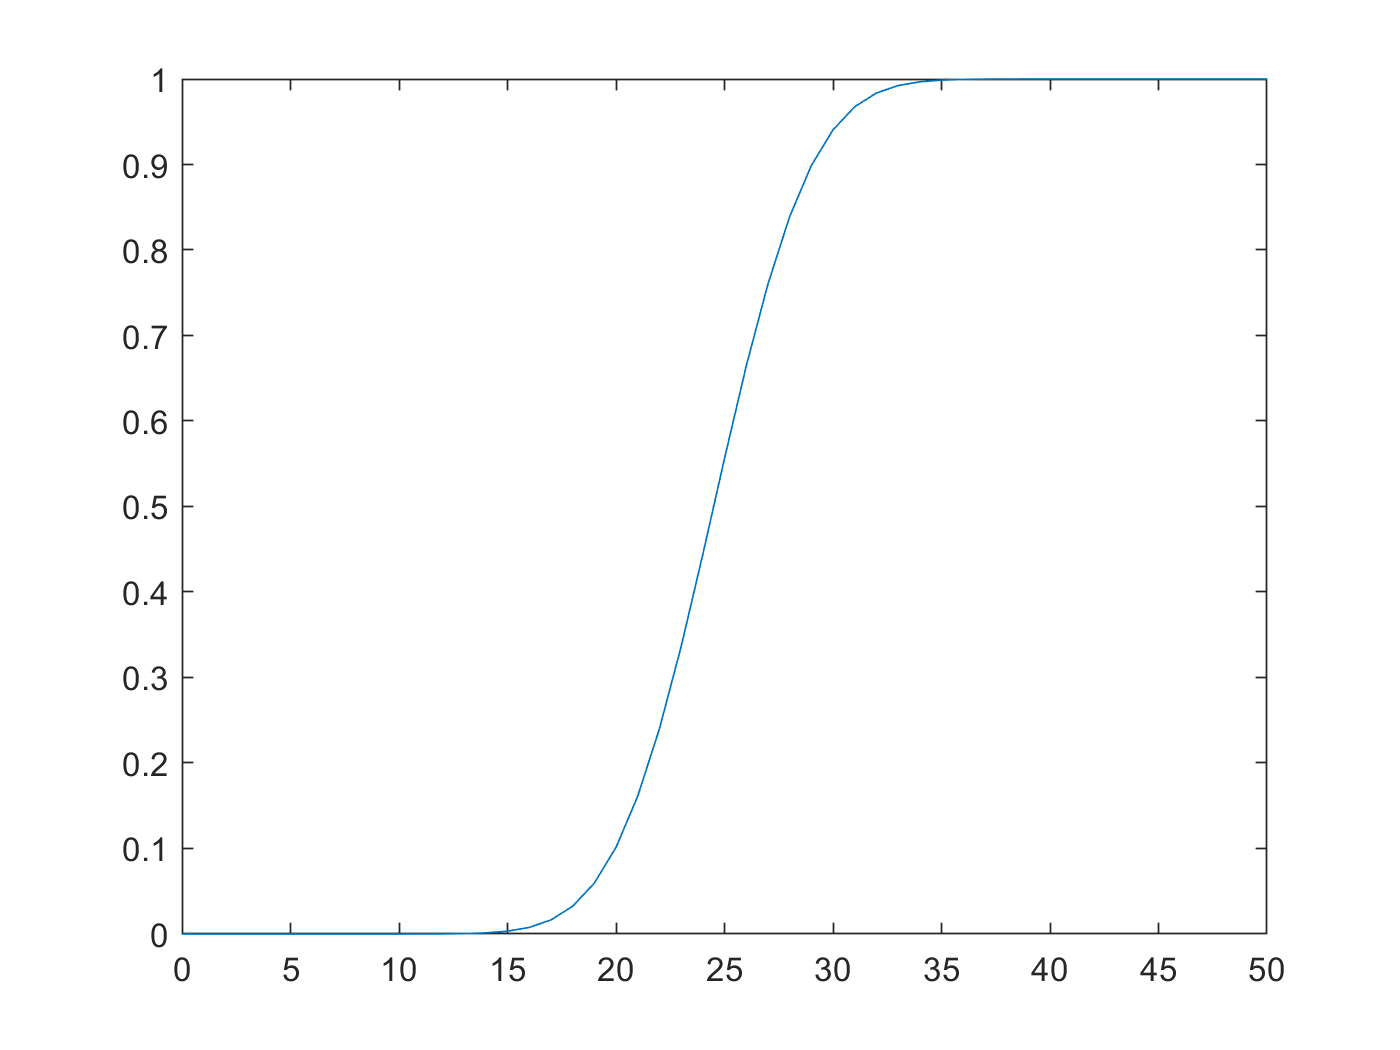

plot(0:50,fb(0:50))

## Fit Data With a Distribution

`fitdist`

- creates a probability distribution object by fitting the distribution specified by `distname` to the data in column vector `x`

- Name and Value pairs can be specified when fitting different distributions

y = randn(10,1);
pdfit = fitdist(y,'Normal')

pdfit =   NormalDistribution

  Normal distribution
       mu = 0.277456   [-0.746807, 1.30172]
    sigma =  1.43182   [0.984857, 2.61395]


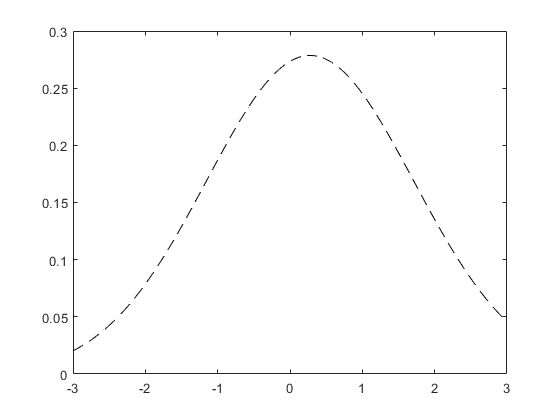

x=linspace(-3,3,100);
plot(x,pdf(pdfit,x),'k--')

To get a better feel for data, you can also fit histograms

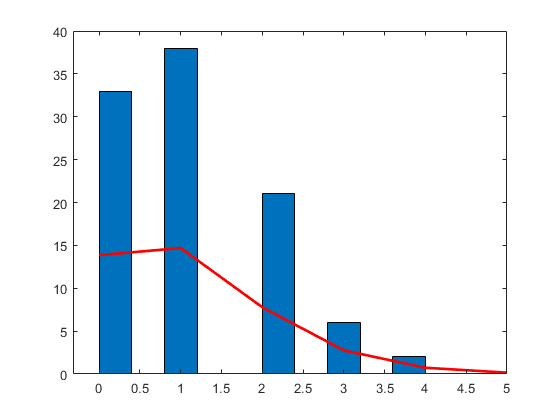

hp =   2×1 graphics array:

  Bar
  Line

pp = makedist('Poisson');
pw = makedist('Weibull');
pn = makedist('Normal');

rp = random(pp,[100,1]);
rw = random(pw,[100,1]);
rn = random(pn,[100,1]);
hp = histfit(rp,10,'poisson')

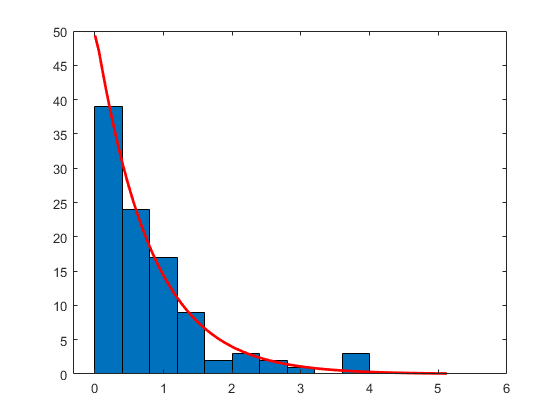

hw =   2×1 graphics array:

  Bar
  Line

hw = histfit(rw,10,'weibull')

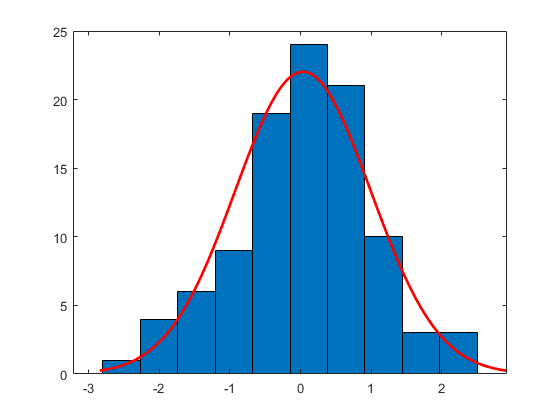

hn =   2×1 graphics array:

  Bar
  Line

hn =histfit(rn)

## Non-Uniform Random Numbers

- `random `can accept probability distribution objects and return random numbers drawn from that distribution

- This function will also accept the `name` of the distribution with appropriate parameters `A`, `B`, ….

**Radioactive simulation revisited:**

- The probability the a particle decays in time *t* is 


$$1-2^{-t/t_{1/2}}$$


- The probability that it decays in a small time period *dt*


$$1-2^{dt/t_{1/2}} = 1-exp\left[\frac{t}{t_{1/2}ln(2)}\right] \approx \frac{dt}{\tau}$$


What is the probability of decay in between the times *t *and *t+dt*?

- The particle has to not decay up to *t*, 


$$P(t) = e^{-t/\tau}$$


- Then during the next *dt**, *


$$P(dt) = \frac{dt}{\tau}$$


- The total probability is then


$$P(t) = e^{-t/\tau}\left(\frac{dt}{\tau}\right)$$


Therefore a “better program” would have drawn from an exponential distribution to represent the times at which a particle decayed

- isotopedecay2.m produces a series of numbers from an exponential distribution to model radioactive decay 

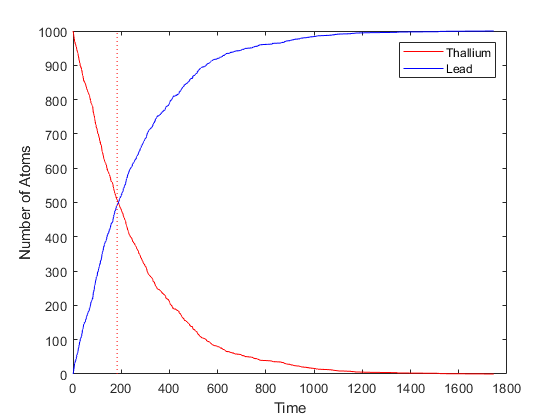

isotopedecay2

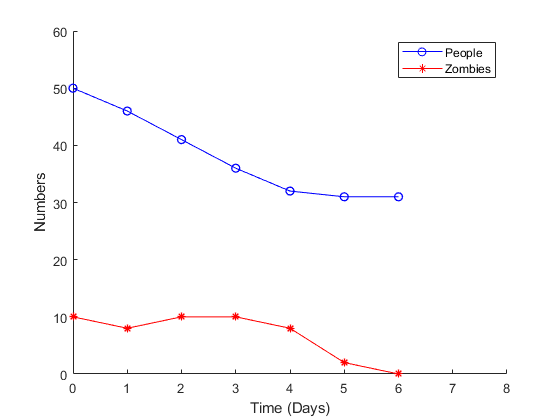

ans = '31 people triumph in 6 days'

ans =      6

zombies(10,50,0.4)